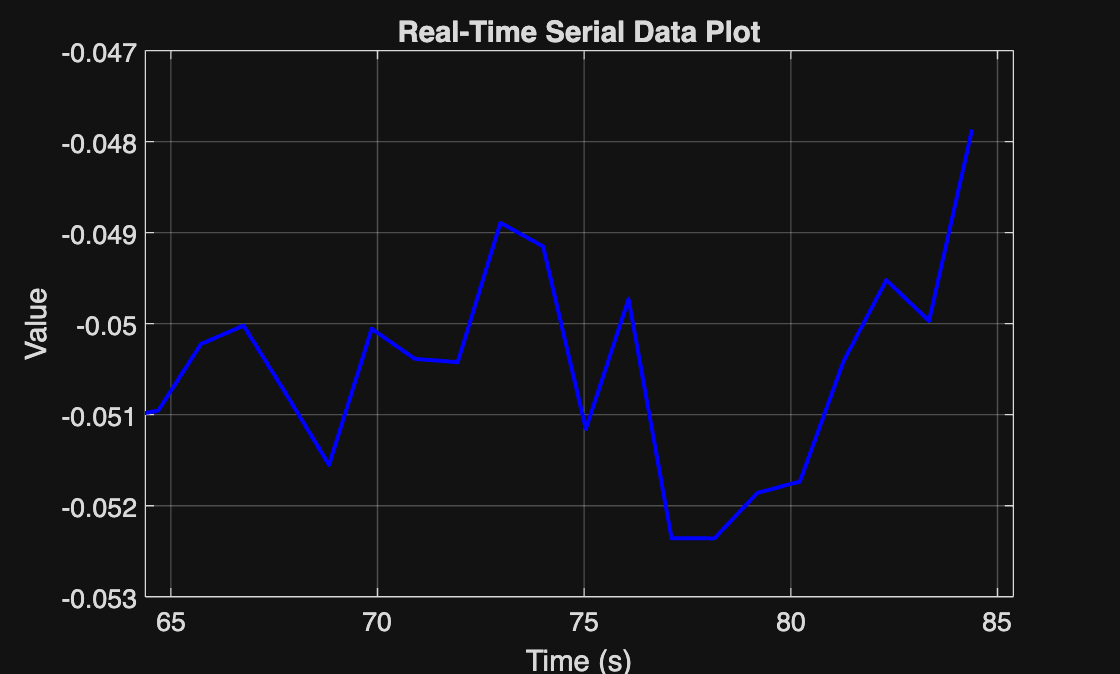

clear; clc; close all;

% Serial Port Configuration
serialPort = '/dev/tty.usbmodem2059325650461'; % CHANGE TO CORRECT PORT
baudRate = 9600;
s = serialport(serialPort, baudRate);
configureTerminator(s, 'LF'); % Assuming newlines separate data blocks

% Data Storage
timeData = [];
valueData = [];
startTime = datetime('now');

% Figure Setup
figure;
h = plot(NaN, NaN, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Value');
title('Real-Time Serial Data Plot');
grid on;
hold on;

% Real-Time Data Acquisition
while true
    rawData = readline(s); % Read incoming data as a line
    
    if contains(rawData, '[')  % Detect start of a new data packet
        continue;
    elseif contains(rawData, ']') % Detect end of a data packet
        pause(1); % Wait for the next packet (1 second interval)
        continue;
    end

    % Extract numeric values from the formatted string
    tokens = regexp(rawData, '(\d+):\s*(-?\d+\.\d+|-?\d+)', 'tokens');
    
    if ~isempty(tokens)
        paramID = str2double(tokens{1}{1}); % Extract parameter ID
        paramValue = str2double(tokens{1}{2}); % Extract parameter value

        if paramID == 3 % Change this to the ID you want to track
            elapsedTime = seconds(datetime('now') - startTime);
            timeData = [timeData, elapsedTime];
            valueData = [valueData, paramValue];

            % Update Plot
            set(h, 'XData', timeData, 'YData', valueData);
            xlim([max(0, elapsedTime - 20), elapsedTime + 1]); % Keep the last 20s visible
            drawnow;
        end
    end
end


% Clean Up
clear s;
